%% read data
[~, words] = textread('features_idx.txt', '%d %s');
[M,y] = readdata();

Class 1: 71 items
Class 2: 68 items
M is 139-by-18446, fraction of nonzero entries: 2.078710e-02


y(y<0) = 2; % Florida = 1; Indiana = 2
k = 23;
[n,m] = size(M);

% computing leverage
[~,~,V] = svd(M, 'econ');
Vk = V(:,1:k);
p = (1/k).*sum(Vk.^2,2);

% finding max k leverage words
[~,ind] = maxk(p,k);
words(ind)

ans = 23×1 cell array
    {'gif'        }
    {'shim'       }
    {'the'        }
    {'clearpixel' }
    {'bullet'     }
    {'spacer'     }
    {'limo'       }
    {'and'        }
    {'jpg'        }
    {'florida'    }
    {'del'        }
    {'rentals'    }
    {'812'        }
    {'you'        }
    {'county'     }
    {'for'        }
    {'radio'      }
    {'church'     }
    {'vanderburgh'}
    {'los'        }
    {'miami'      }
    {'evansville' }
    {'uruguaysc'  }


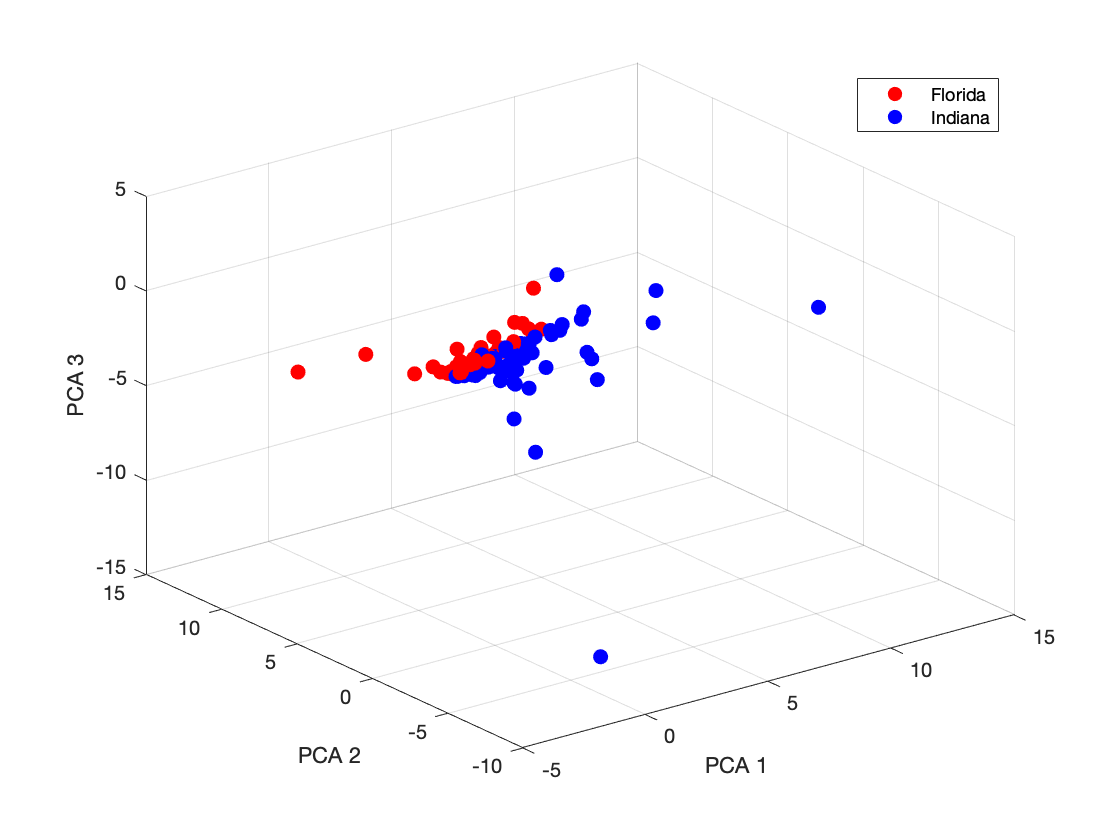


% project on to principle components with small M
M_ = M(:,ind);

% project onto the first 2 principal components
PCA(M_,y,'figures/cur_pca_3d.png',3);

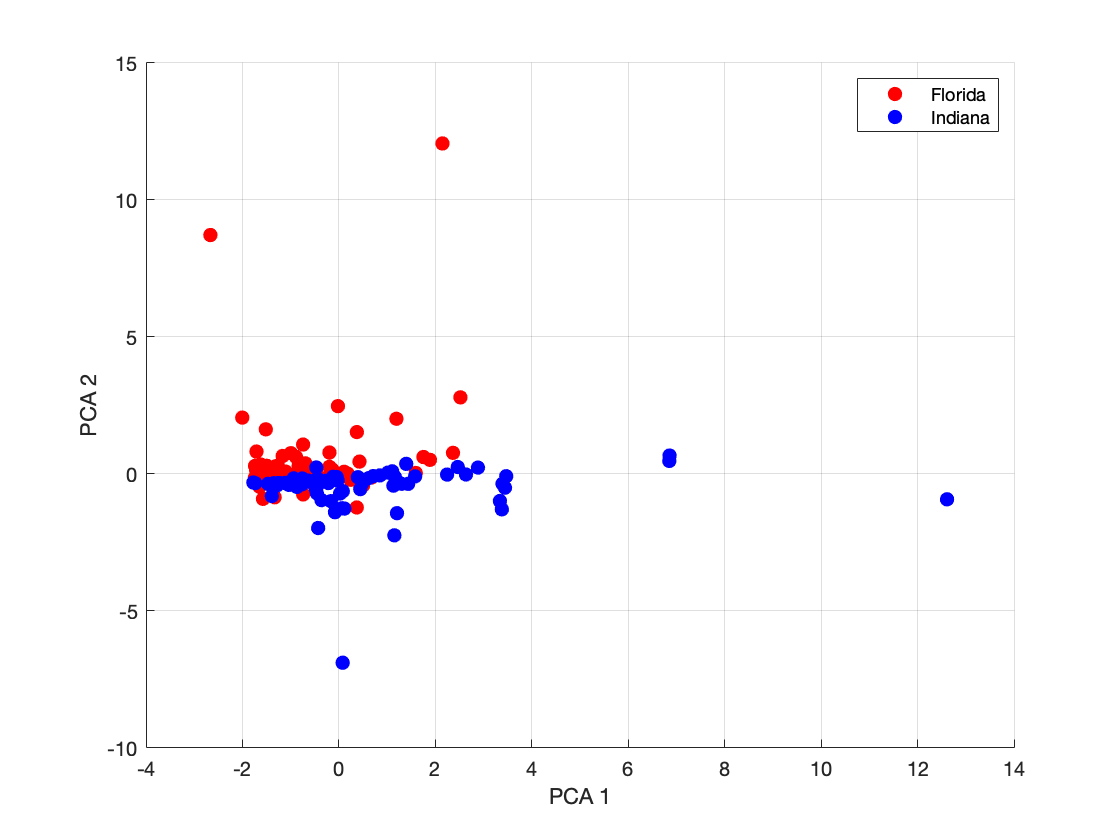

PCA(M_,y,'figures/cur_pca_2d.png',2);

%% preprocessing
[M_str, strs] = Preprocess(M,words);
strs

strs =      1
     2
     3
     5
     9
    12
    13
    14
    15
    16



[C,~,~] = CUR(M_str,10000,k);
M_str = C

M_str =     54    11    53    44    11     2     6    14     6     9     7     6     6     4     4     8    14     8     4     4     2     4    10    10     2     2    12    13     7     3     5     3    13     7     3     7     5     1    18     8    36     4     4     4     4     4    16     4    12     8
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     0
     6     0     0     0     0     0     0     0     0     0     0     0     0     0     

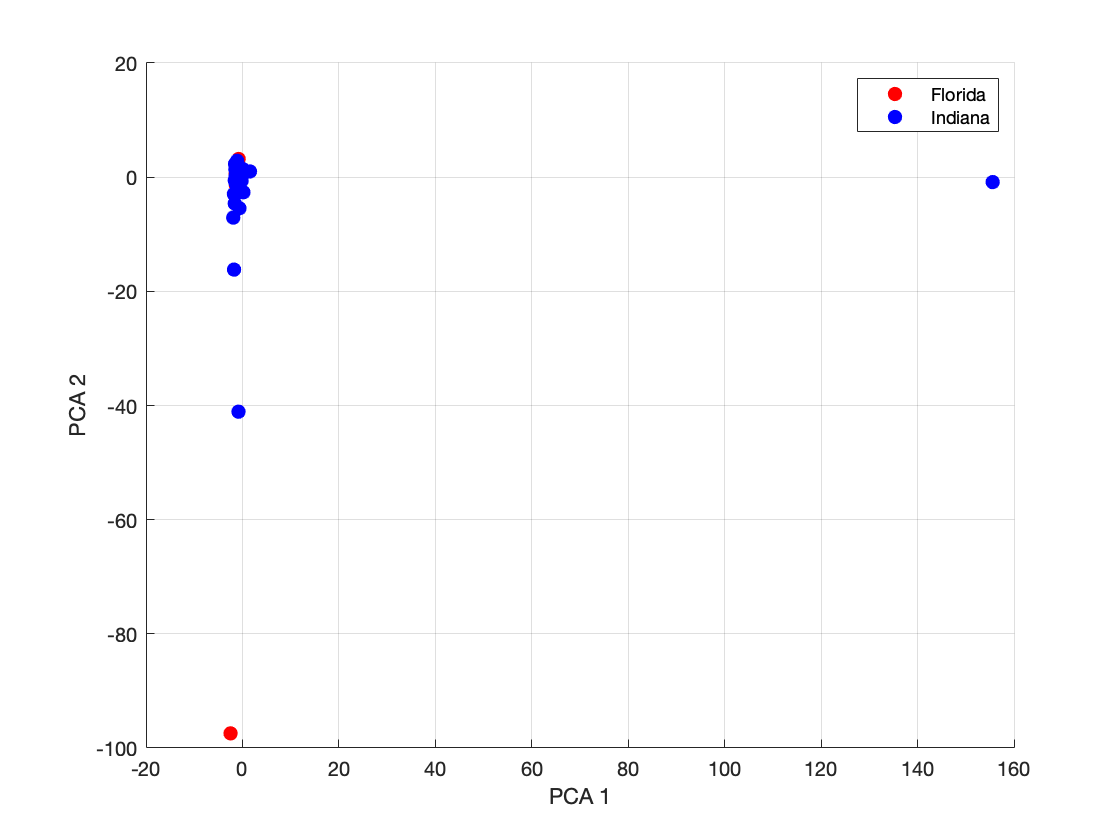

PCA(M_str,y,'figures/cur_10k_2d.png',2)

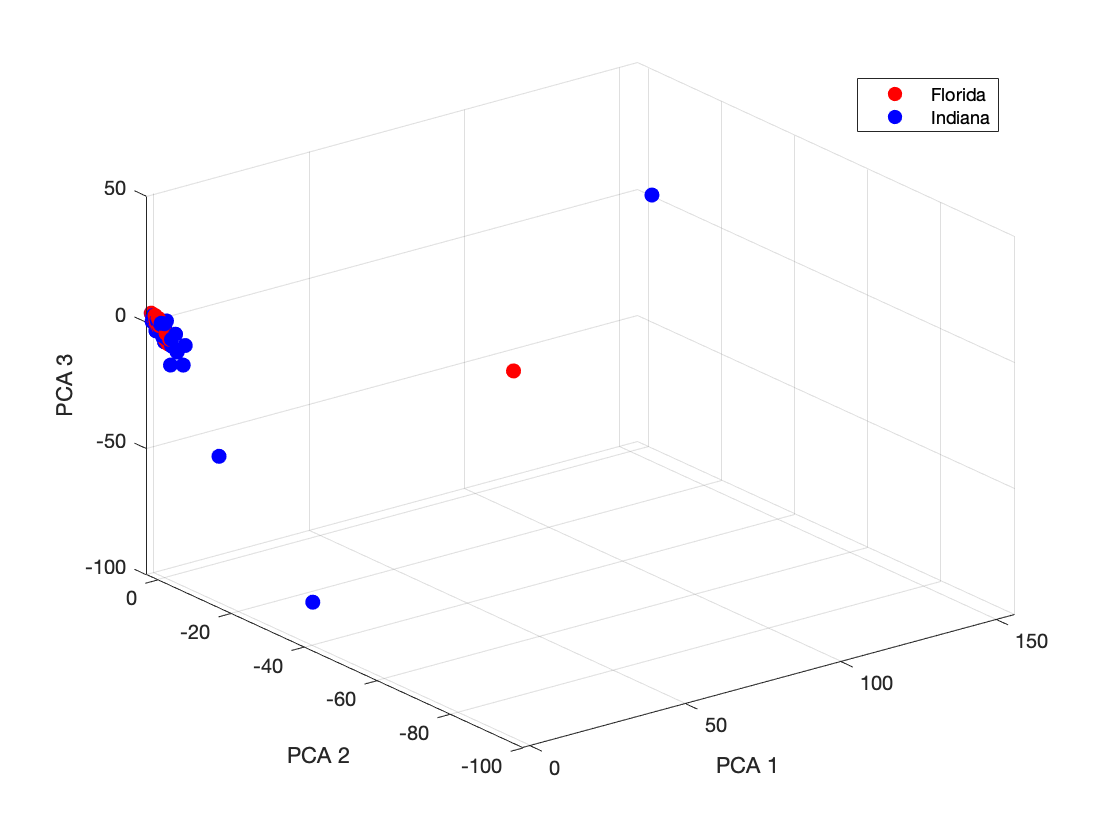

PCA(M_str,y,'figures/cur_10k_3d.png',3)


% computing leverage
[~,~,V] = svd(C, 'econ');
Vk = V(:,1:k);
p = (1/k).*sum(Vk.^2,2);

% finding max k leverage words
[~,ind] = maxk(p,5);
words(strs(ind))

ans = 5×1 cell array
    {'resources'}
    {'little'   }
    {'unshaven' }
    {'notion'   }
    {'florida'  }


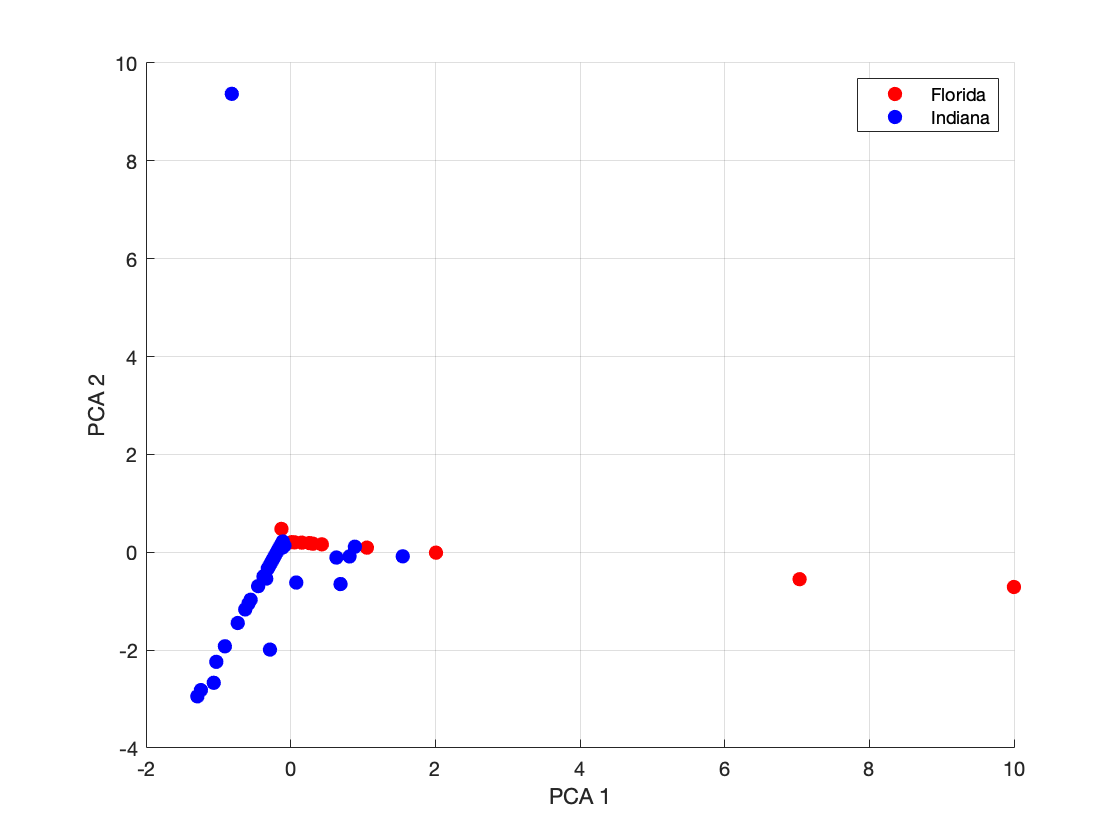


% project on to principle components with small M
M_ = M_str(:,ind);

% project onto the first 2 principal components
PCA(M_,y,'figures/cur_10k_5_2d.png',2)

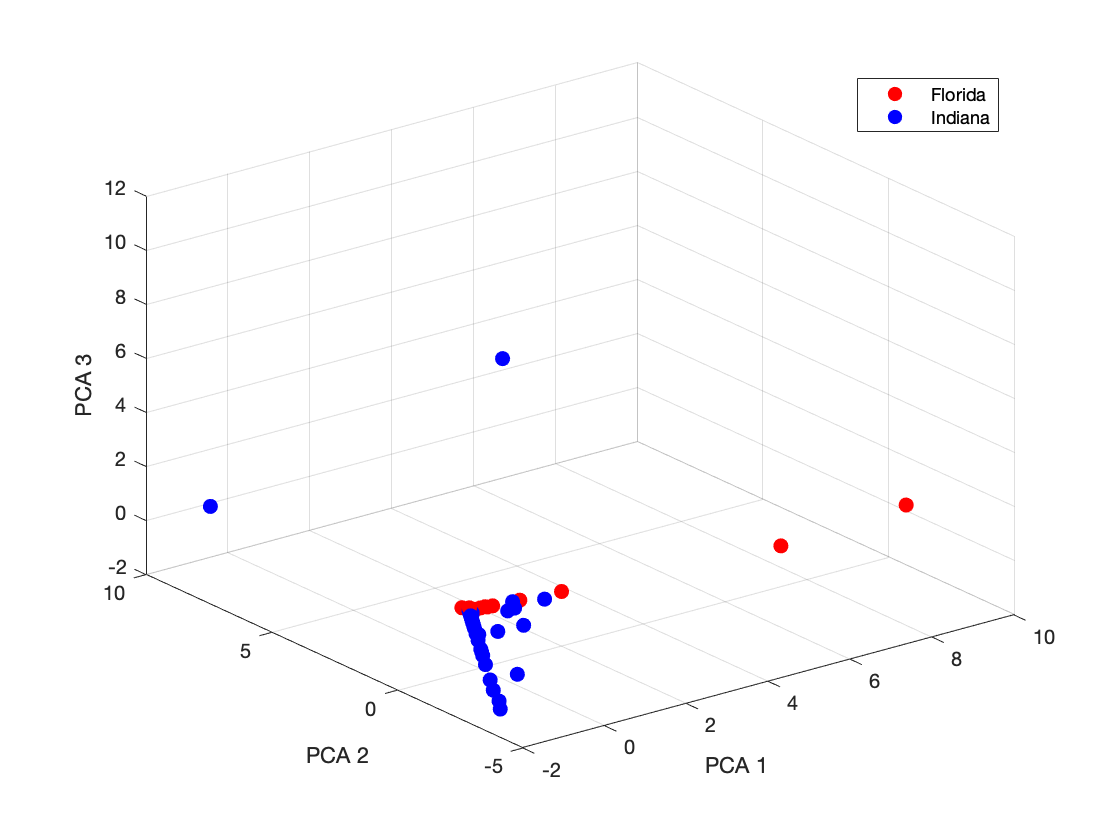

C =     54    23    19     6     7    18    12    18    16     4     4     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     2     9    11     0     4     0     0     1     0     2     1     1     4     1     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     6    21    17     2     4     5     1     0     1     6     3     1     0     0     0     2     0     0   

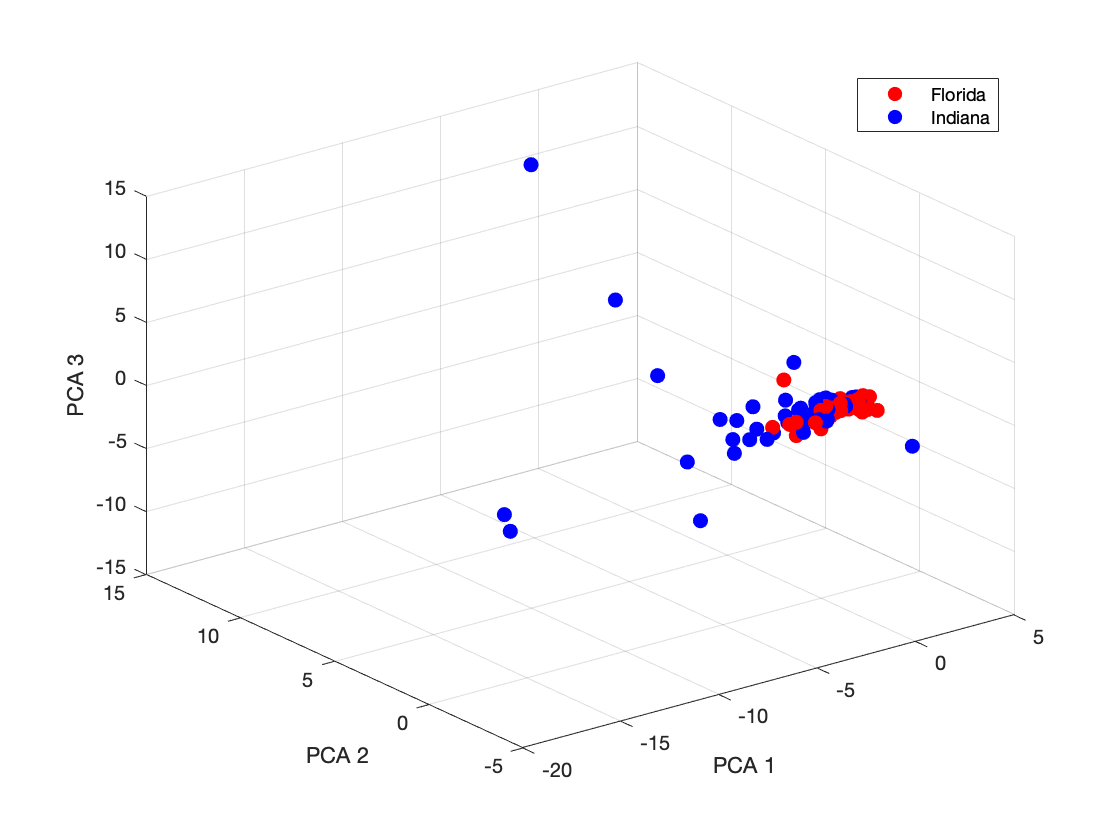

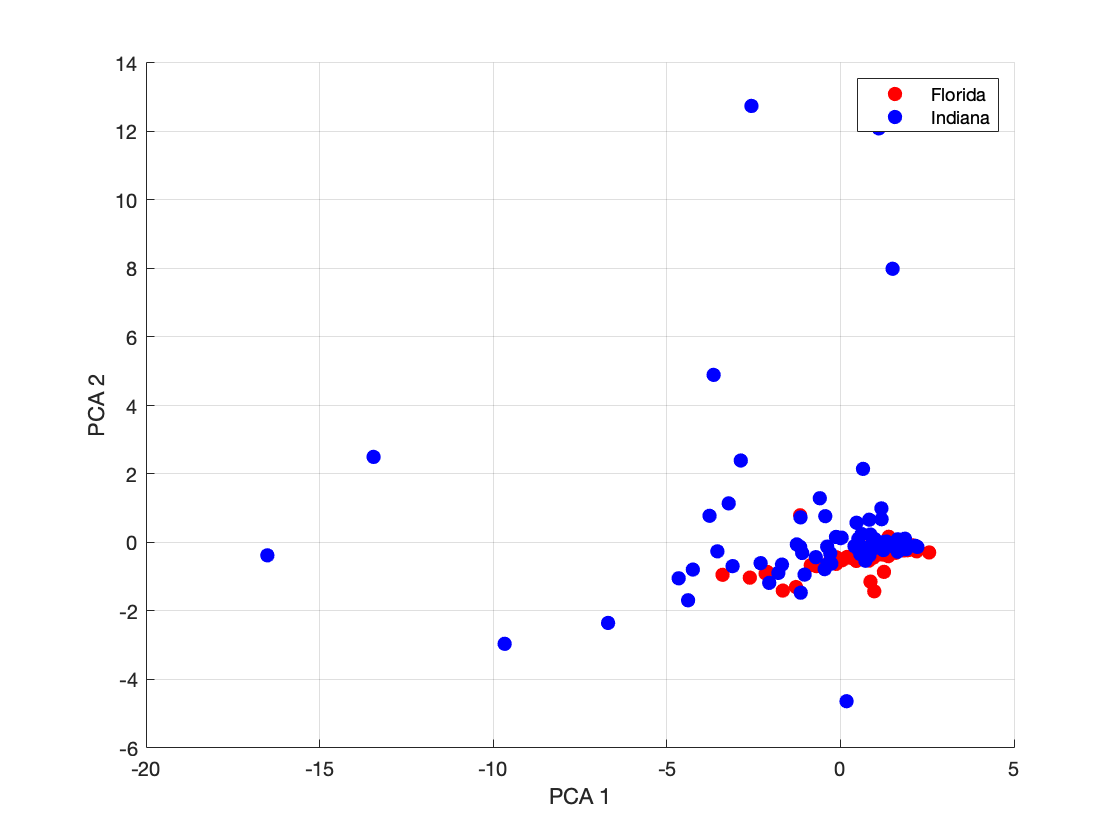

ans = 5×1 cell array
    {'can'     }
    {'erickson'}
    {'the'     }
    {'closing' }
    {'baby'    }


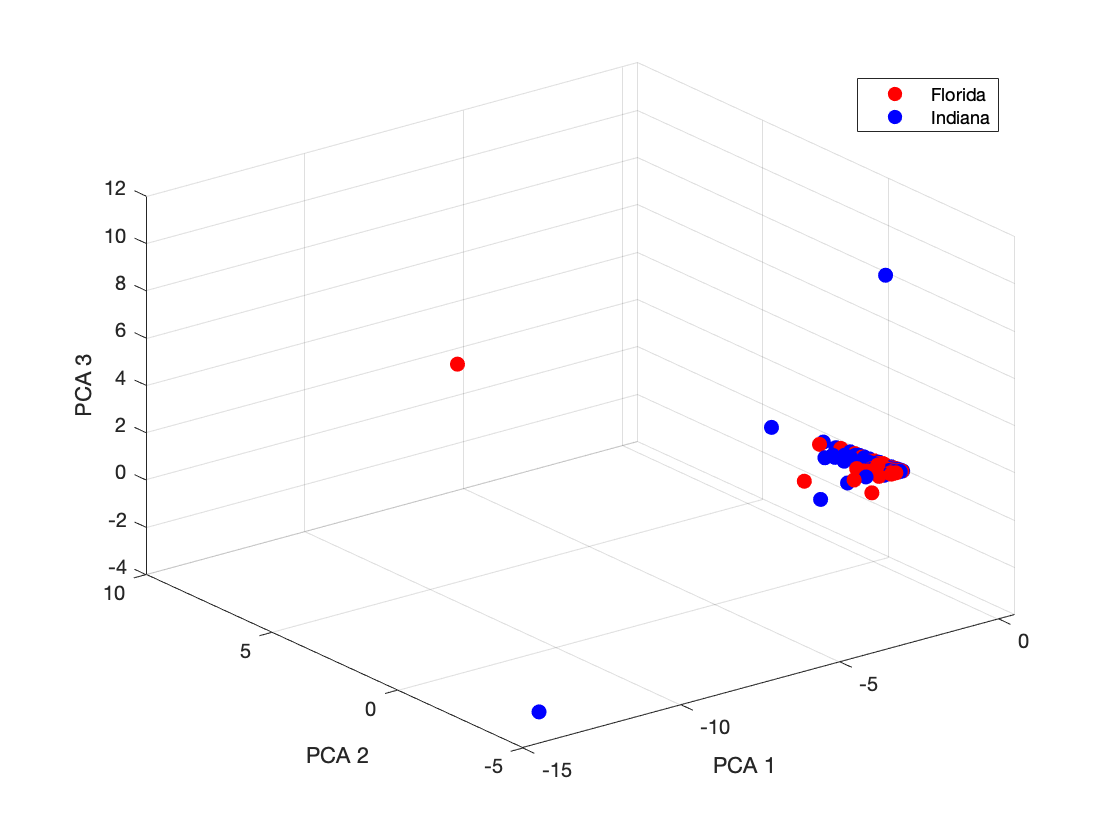

ans = 23×1 cell array
    {'gif'         }
    {'insulation'  }
    {'the'         }
    {'mythic'      }
    {'picking'     }
    {'clements'    }
    {'and'         }
    {'305-447-9898'}
    {'directory'   }
    {'florida'     }
    {'arriba'      }
    {'considerably'}
    {'teachers'    }
    {'3687'        }
    {'you'         }
    {'rental'      }
    {'usually'     }
    {'for'         }
    {'djs'         }
    {'your'        }
    {'courtney'    }
    {'diameter'    }
    {'miami'       }


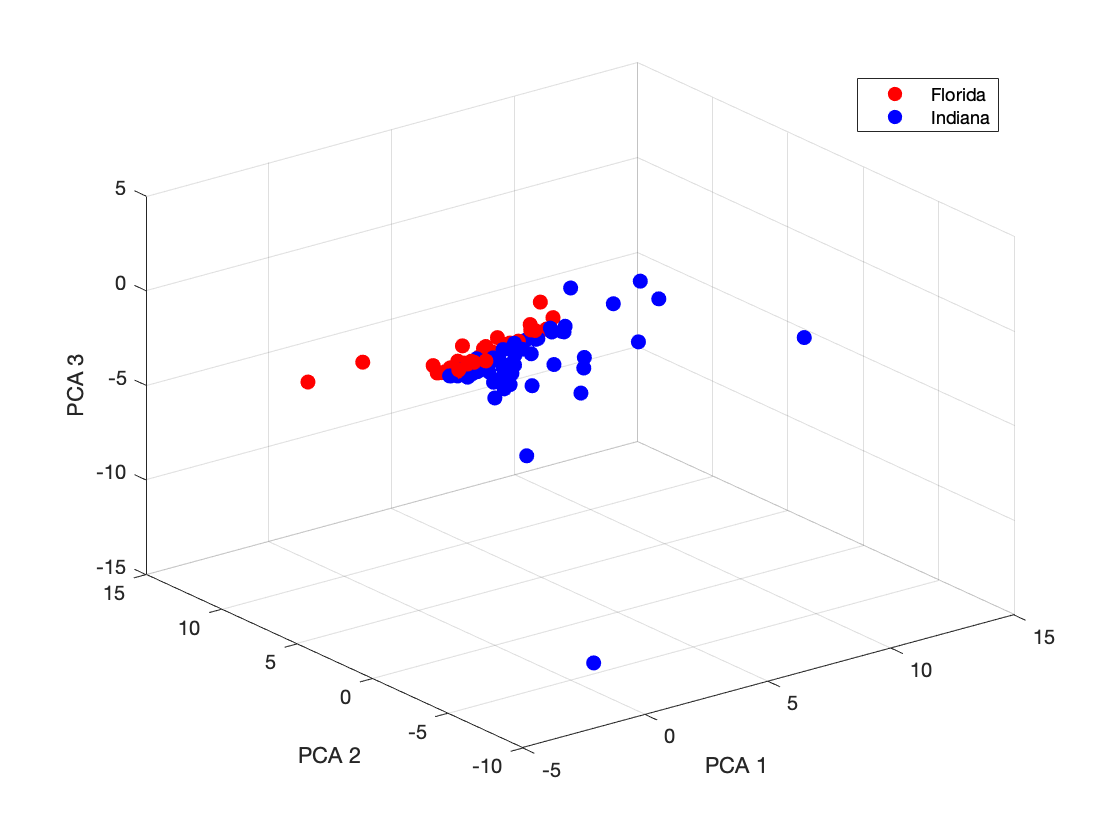

PCA(M_,y,'figures/cur_10k_5_3d.png',3)

% finding max k leverage words
[~,ind] = maxk(p,23);
words(strs(ind))

ans = 23×1 cell array
    {'resources'    }
    {'little'       }
    {'unshaven'     }
    {'notion'       }
    {'florida'      }
    {'organizations'}
    {'praise'       }
    {'please'       }
    {'course'       }
    {'locations'    }
    {'transactions' }
    {'friendships'  }
    {'village'      }
    {'composed'     }
    {'ranch'        }
    {'parkway'      }
    {'confronta'    }
    {'gables'       }
    {'express'      }
    {'twice'        }
    {'school'       }
    {'faith'        }
    {'concerns'     }


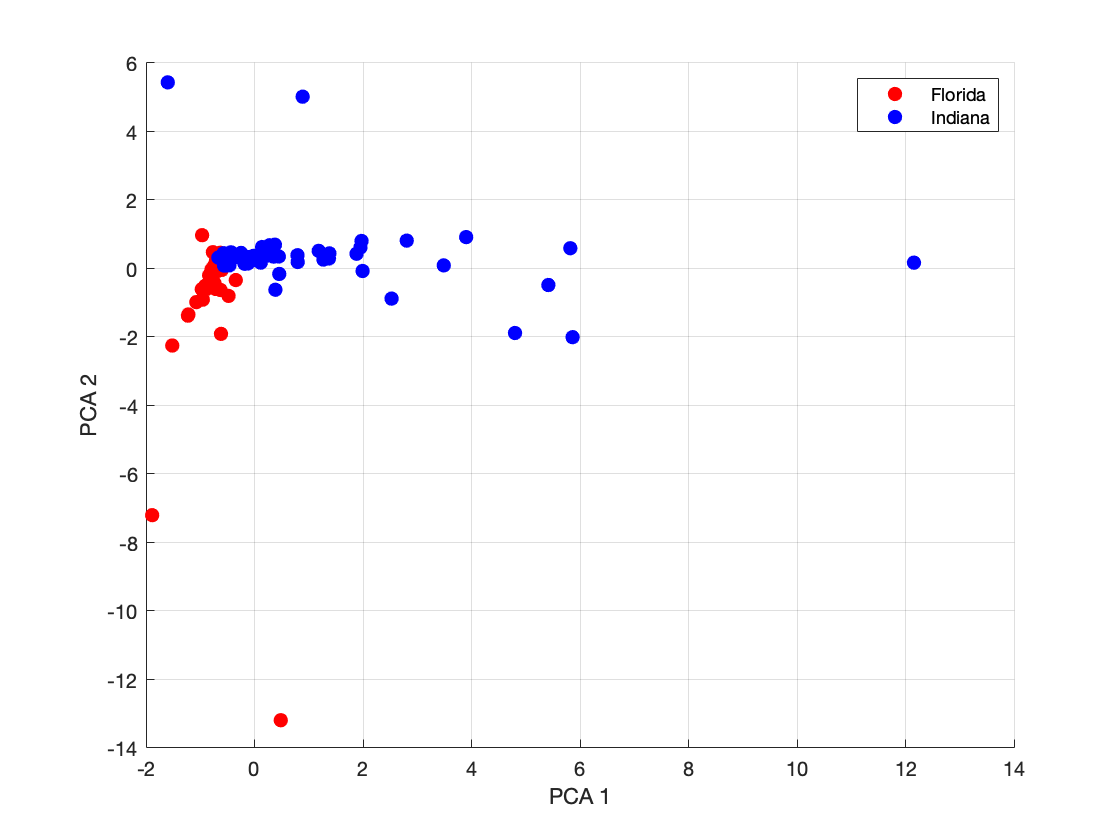


% project on to principle components with small M
M_ = M_str(:,ind);

% project onto the first 2 principal components
PCA(M_,y,'figures/cur_10k_23_2d.png',2)

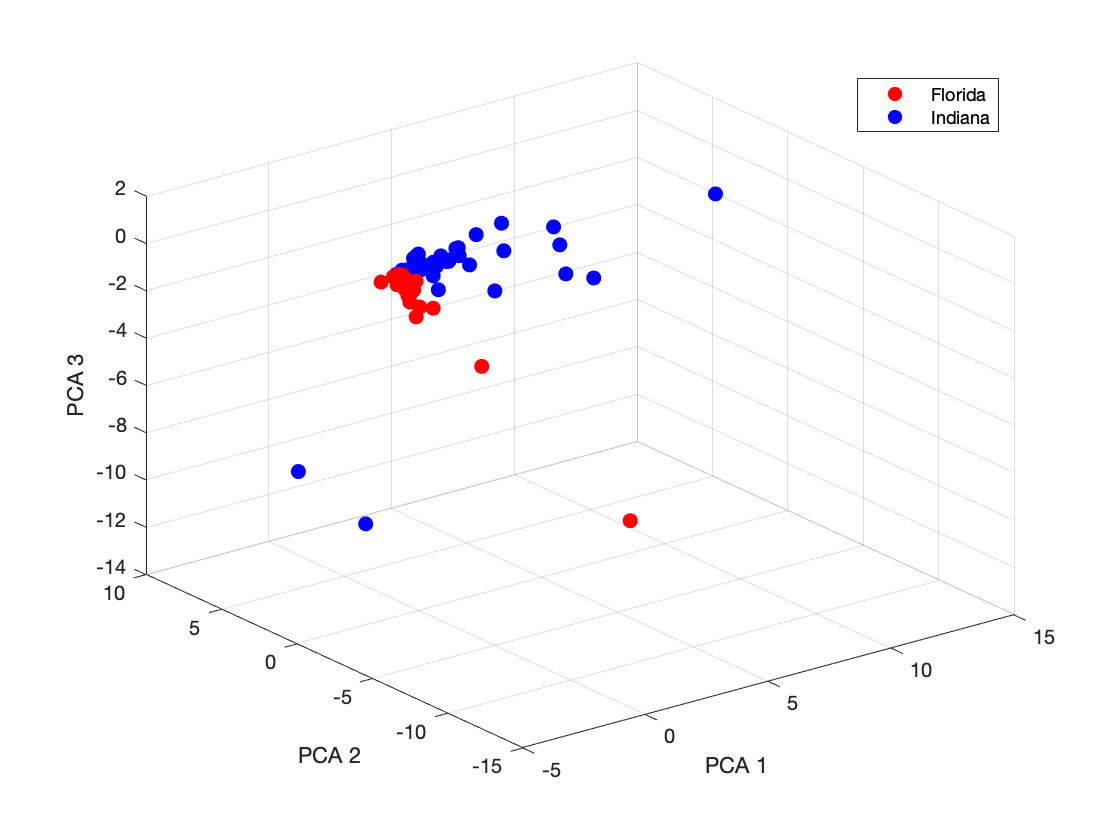

PCA(M_,y,'figures/cur_10k_23_3d.png',3)